% Author: Yu-Chuan Chen IOC Academia Sinica, Tawain
% Last update: July 22, 2019

## Path to file with the path data

matFilePath = '/Yu-Chuan/MATLAB/Working_Tm/mat_files/';

load( strcat( matFilePath, 'workingDateAndLab', '.mat'))

load( strcat( matFilePath, 'dendriticLengthDistributionData_TmRoot_', lab_name, '_', date, '.mat' ) )

directory_out = '/Yu-Chuan/MATLAB/Working_Tm/figure/NewKbAndKt/';

neuronType = 'Tm'

neuronType = 'Tm'

dendriteType = {};

%%%%%%%%%%%%%%%%%%%%%%%%
for cx = 1: numberOfClasses
    
    modeOfStructureFlag = mode( structureFlag(cx, 1: numberOfNeuronsInClass(cx)));
        
        if modeOfStructureFlag  == 1
    
            dendriteType ={'allDendrite'};
    
        elseif modeOfStructureFlag == 2
    
            dendriteType ={'Dendrite'};
    
        elseif modeOfStructureFlag == 3
    
            dendriteType ={'basal'};

        elseif modeOfStructureFlag == 4
    
            dendriteType={'apical'};
    
        else
    
           dendriteType ={'basal', 'apical'};
    
        end
        
end % end of cx

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

## Parameter Setting

showCut = floor(0.8 * length(lenRange));

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

## Plot mean and sd of KB and KT

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
figureOutputPath = strcat(directory_out, 'numberChange/', lab_name, '/');
folderExist = exist(figureOutputPath, 'dir');
if folderExist == 0
     mkdir(figureOutputPath)
end

## for branching

for cx  = 1: numberOfClasses
        
     for tx = 1: size(groupOfKB, 2) 
     
            for ix = 1: size(groupOfKB{cx, tx}, 1)

## plot only <= 1

                B_element =  groupOfKB{cx, tx}(ix, :);
                B_less1 = B_element(B_element <= 1);
                
                plot(B_less1, 'Color', [0, 1, 1])
        
                hold on
    
            end        
         
         rm0OfGroupOfKB = groupOfKB{cx, tx}(groupOfAtRisk{cx, tx}(:, 1) ~= 0, :);

## mean of KB less than 1

         for  clx = 1: showCut 
            
            column = rm0OfGroupOfKB(: , clx);

## column <= 1 and isNaN

## mean of KB less than 1

            ColumnLess1AndNotNaN = column(column <= 1 & ~isnan(column));
            sumColumnLess1 = sum(ColumnLess1AndNotNaN);
            meanOfKB(clx) = sumColumnLess1 / length(ColumnLess1AndNotNaN);

## std of KB less than 1 and

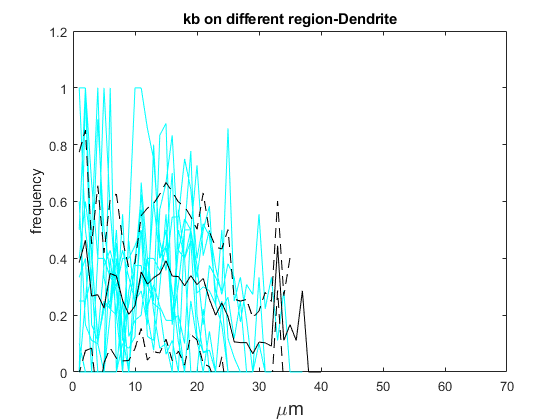

            square = (ColumnLess1AndNotNaN - meanOfKB(clx)) .* (ColumnLess1AndNotNaN - meanOfKB(clx));
            stdOfKB(clx) = (sum(square) / (length(ColumnLess1AndNotNaN) -1))^(1/2);
            
         end
         
          
         upbound_risk = meanOfKB + stdOfKB;
         downbound_risk = meanOfKB - stdOfKB;
    
         plot(meanOfKB, 'k')
         plot(upbound_risk , '--k') 
         plot(downbound_risk, '--k')

        axis( [ 0 70 0 1.2 ] )
    
        title(strcat('kb on different region-', dendriteType{tx}))
        xlabel ('\mum', 'FontSize', 14)
        ylabel ('frequency')
    
        hold off
    
        saveFileNams = strcat(figureOutputPath , 'kb_region_', neuronType, '_', lab_name, '_',neuron_names{cx}, dendriteType{tx}, '.fig');
        saveas(gcf, saveFileNams, 'fig') ;
        saveFileNams = strcat(figureOutputPath , 'kb_region_', neuronType, '_', lab_name, '_',neuron_names{cx}, dendriteType{tx}, '.png');
        saveas(gcf, saveFileNams, 'png') ;
       
    end % end of tx
     
end % end of cx

## for terminal %%%%%%%%%%%%%%%%%%%%%%%%%%%%%

for cx  = 1: numberOfClasses
        
     for tx = 1: size(groupOfKT, 2) 
     
            for ix = 1: size(groupOfKT{cx, tx}, 1)

## plot only <= 1

                T_element =  groupOfKB{cx, tx}(ix, :);
                T_less1 = T_element(T_element <= 1);
                
                plot(T_less1, 'Color', [0, 1, 1])
        
                hold on
    
            end        
         
            
         rm0OfGroupOfKT = groupOfKT{cx, tx}(groupOfAtRisk{cx, tx}(:, 1) ~= 0, :);

## mean of KT less than 1

         for  clx = 1: showCut 
            
            column = rm0OfGroupOfKT(: , clx);

## column <= 1 and isNaN

## mean of KT less than 1

            ColumnLess1AndNotNaN = column(column <= 1 & ~isnan(column));
            sumColumnLess1 = sum(ColumnLess1AndNotNaN);
            meanOfKT(clx) = sumColumnLess1 / length(ColumnLess1AndNotNaN);

## std of KB less than 1 and

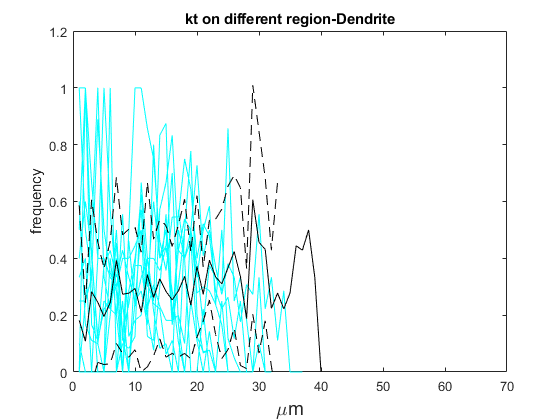

            square = (ColumnLess1AndNotNaN - meanOfKT(clx)) .* (ColumnLess1AndNotNaN - meanOfKT(clx));
            stdOfKT(clx) = (sum(square) / (length(ColumnLess1AndNotNaN) -1))^(1/2);
            
         end
         
         
         upbound_risk = meanOfKT + stdOfKT;
         downbound_risk = meanOfKT - stdOfKT;
    
         plot(meanOfKT, 'k')
         plot(upbound_risk , '--k') 
         plot(downbound_risk, '--k')

        axis( [ 0 70 0 1.2 ] )
    
        title(strcat('kt on different region-', dendriteType{tx}))
        xlabel ('\mum', 'FontSize', 14)
        ylabel ('frequency')
    
        hold off
    
        saveFileNams = strcat(figureOutputPath , 'kt_region_', neuronType, '_', lab_name, '_',neuron_names{cx}, dendriteType{tx}, '.fig');
        saveas(gcf, saveFileNams, 'fig') ;
        saveFileNams = strcat(figureOutputPath , 'kt_region_', neuronType, '_', lab_name, '_',neuron_names{cx}, dendriteType{tx}, '.png');
        saveas(gcf, saveFileNams, 'png') ;
       
    end % end of tx
     
end % end of cx


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

## Plot segment number change

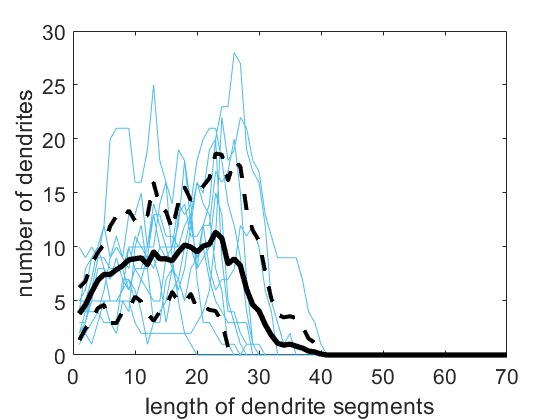

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
figure;
OutputOfAtRsk = strcat(directory_out, 'numberChange/AtRisk/', lab_name, '/');
folderExist = exist(OutputOfAtRsk , 'dir');
if folderExist == 0
     mkdir(OutputOfAtRsk)
end

OutputOfAtRsk_excel = strcat(directory_out, 'numberChange/AtRisk/Excel/', lab_name, '/');
folderExist = exist(OutputOfAtRsk_excel , 'dir');
if folderExist == 0
     mkdir(OutputOfAtRsk_excel)
end

for cx = 1: numberOfClasses
    
    for tx = 1: size(groupOfAtRisk, 2)
    
        for nx = 1: numberOfNeuronsInClass(cx)
    
            plot(groupOfAtRisk{cx, tx}(nx, :), 'Color', [0.3010, 0.7450, 0.9330])
    
            hold on
    
        end
    
        rm0OfGroupOfAtRisk = groupOfAtRisk{cx, tx}(groupOfAtRisk{cx, tx}(:, 1) ~= 0, :);
        meanOfAtrisk = nanmean(rm0OfGroupOfAtRisk, 1);
        stdOfAtrisk = nanstd(rm0OfGroupOfAtRisk, 1) ;
 
        upbound_risk = meanOfAtrisk+ stdOfAtrisk;
        downbound_risk = meanOfAtrisk - stdOfAtrisk;
    
        plot(meanOfAtrisk, 'k', 'LineWidth', 4)
        plot(upbound_risk , '--k', 'LineWidth', 3) 
        plot(downbound_risk, '--k',  'LineWidth', 3)

        
        axis( [ 0 70 0 30 ] )
        %title(strcat('segment at risk on different region-',dendriteType{tx}))
        xlabel ('length of dendrite segments')
        ylabel ('number of dendrites')

        hold off
        set(gca,'FontSize',16)
        saveFileNams = strcat(OutputOfAtRsk  , 'segment at risk_region_', neuronType, '_', lab_name, '_',neuron_names{cx},dendriteType{tx}, '.fig');
        saveas(gcf, saveFileNams, 'fig') ;
        saveFileNams = strcat(OutputOfAtRsk  , 'segment at risk_region_', neuronType, '_', lab_name, '_',neuron_names{cx},dendriteType{tx},'.png');
        saveas(gcf, saveFileNams, 'png') ;
        
        saveFileNams = strcat(OutputOfAtRsk_excel, 'NumberChange_', neuronType, '_', lab_name, '_',neuron_names{cx},'_', dendriteType{tx},'.csv');
        csvwrite( saveFileNams, meanOfAtrisk')
    
    end % end of tx
    
end %end of cx


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

## Plot only mean of KB and KT

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
figure;
meanFigureOutputPath = strcat(directory_out, 'MeanKBKT/', lab_name, '/');
folderExist = exist(meanFigureOutputPath , 'dir');
if folderExist == 0
     mkdir(meanFigureOutputPath)
end


for cx = 1 : numberOfClasses
    
    for tx = 1: size(groupOfKB, 2)
       
       rm0OfGroupOfKB = groupOfKB{cx, tx}(groupOfAtRisk{cx, tx}(:, 1) ~= 0, :);
       rm0OfGroupOfKT = groupOfKT{cx, tx}(groupOfAtRisk{cx, tx}(:, 1) ~= 0, :); 
        
       for  clx = 1: showCut
           
            column = rm0OfGroupOfKB(: , clx);

## column <= 1 and isNaN

## mean of KB less than 1

            ColumnLess1AndNotNaN = column(column <= 1 & ~isnan(column));
            sumColumnLess1 = sum(ColumnLess1AndNotNaN);
            meanOfKB(clx) = sumColumnLess1 / length(ColumnLess1AndNotNaN);
          
            column = rm0OfGroupOfKT(: , clx);

## column <= 1 and isNaN

## mean of KT less than 1

            ColumnLess1AndNotNaN = column(column <= 1 & ~isnan(column));
            sumColumnLess1 = sum(ColumnLess1AndNotNaN);
            meanOfKT(clx) = sumColumnLess1 / length(ColumnLess1AndNotNaN);
    
       end

## plot

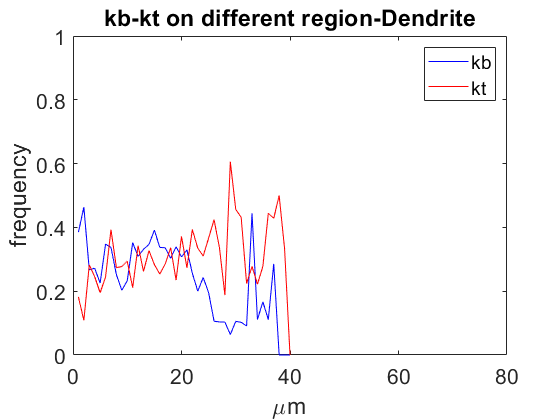

       plot(bins(1: showCut), meanOfKB, 'b') 
       hold on
 
       plot(bins(1: showCut),  meanOfKT, 'r')
       axis( [ 0 80 0 1 ] )

        title(strcat('kb-kt on different region-',dendriteType{tx}) )
        xlabel ('\mum')
        ylabel ('frequency')
        legend({'kb', 'kt'})
        hold off
    
        set(gca,'FontSize',16)
        saveFileNams = strcat(meanFigureOutputPath , 'kb-kt on regionM_', neuronType, '_', lab_name, '_',neuron_names{cx},dendriteType{tx}, '.fig');
        saveas(gcf, saveFileNams, 'fig') ;
        saveFileNams = strcat(meanFigureOutputPath, 'kb-kt on regionM_', neuronType, '_', lab_name, '_',neuron_names{cx},dendriteType{tx}, '.png');
        saveas(gcf, saveFileNams, 'png') ;

    end % end of tx
    
end % end of cx



%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

## Plot Specical Region of Mean of kb and kt

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
figure;
meanSFigureOutputPath = strcat(directory_out, 'MeanKBKT/SpecialRegion/', lab_name, '/');
folderExist = exist(meanSFigureOutputPath , 'dir');
if folderExist == 0
     mkdir(meanSFigureOutputPath)
end

for cx = 1 : numberOfClasses

    for tx =1: size(groupOfKB, 2)
        
        for  clx = 1: showCut
           
            column = rm0OfGroupOfKB(: , clx);

## column <= 1 and isNaN

## mean of KB less than 1

            ColumnLess1AndNotNaN = column(column <= 1 & ~isnan(column));
            sumColumnLess1 = sum(ColumnLess1AndNotNaN);
            meanOfKB(clx) = sumColumnLess1 / length(ColumnLess1AndNotNaN);
          
            column = rm0OfGroupOfKT(: , clx);

## column <= 1 and isNaN

## mean of KT less than 1

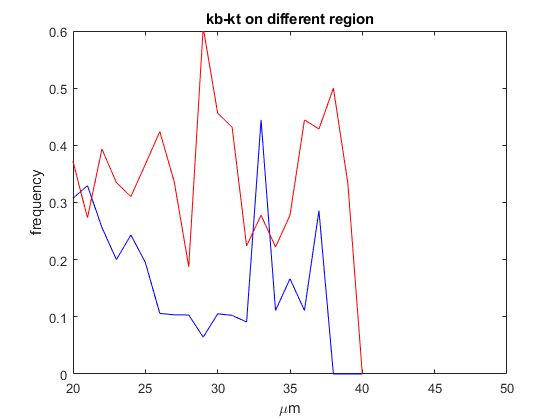

            ColumnLess1AndNotNaN = column(column <= 1 & ~isnan(column));
            sumColumnLess1 = sum(ColumnLess1AndNotNaN);
            meanOfKT(clx) = sumColumnLess1 / length(ColumnLess1AndNotNaN);
    
        end    

    plot(bins(1: showCut), meanOfKB, 'b')
    hold on

    plot(bins(1: showCut),  meanOfKT, 'r')

    axis( [ 20 50  0 0.6 ] )

    title('kb-kt on different region')
    xlabel ('\mum')
    ylabel ('frequency')
    hold off

    saveFileNams = strcat(meanFigureOutputPath , 'kb-kt on regionM_', neuronType, '_', lab_name, '_',neuron_names{cx},'.fig');
    saveas(gcf, saveFileNams, 'fig') ;
    saveFileNams = strcat(meanFigureOutputPath, 'kb-kt on regionM_', neuronType, '_', lab_name, '_',neuron_names{cx},'.png');
    saveas(gcf, saveFileNams, 'png') ;
    
    end

end




%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

## plot imagesc

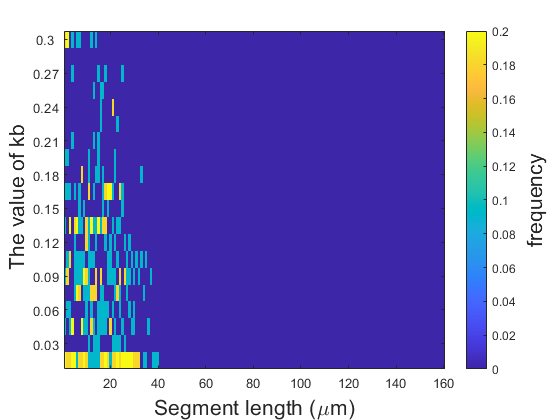

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%    
%%%for branching
% data up-limit

outputOfImagesc = strcat(directory_out ,'histogram of mean/TimeSeriesOfKbKt/',  lab_name, '/');

folderExist = exist(outputOfImagesc, 'dir');
if folderExist == 0
     mkdir(outputOfImagesc)
end


edges = 0: 0.05: 1.0;


for cx = 1: numberOfClasses
    
    kbOftmeSeries = [];
    
    for tx = 1: size(groupOfKB, 2)
        
        for ii = 1: showCut
   
            h  = histogram(groupOfKB{cx, tx}(:, ii), edges, 'Normalization','probability');
            
            kbOftmeSeries = [kbOftmeSeries, h.Values']; 
   
        end
   
        clims = [0, 0.2];
        
        yy= 0.03: 0.03: 0.3;
        
        imagesc(kbOftmeSeries, clims);

        set(gca,'ydir','normal')  %%%  y-axis down-to-up
        set(gca, 'YTickLabel', yy)
        %set(gca,  'XTickLabel', xx, 'FontSize', 8)
        xlabel('Segment length (\mum)', 'FontSize', 16);
        ylabel(' The value of kb' ,'FontSize', 16);
        colorbar()
        ff = colorbar;
        ylabel(ff, 'frequency', 'FontSize', 16);
        set(ff, 'ylim', [0, clims(2)])

        saveFileNams = strcat(outputOfImagesc , 'Time series distribution of kb_', neuronType, '_', lab_name, '_',neuron_names{cx}, dendriteType{tx}, '.fig');
        saveas(gcf, saveFileNams, 'fig') ;
        saveFileNams = strcat(outputOfImagesc , 'Time series distribution of kb_', neuronType, '_', lab_name, '_',neuron_names{cx}, dendriteType{tx}, '.png');
        saveas(gcf, saveFileNams, 'png') ;

    end % end of tx
    
end % end of cx

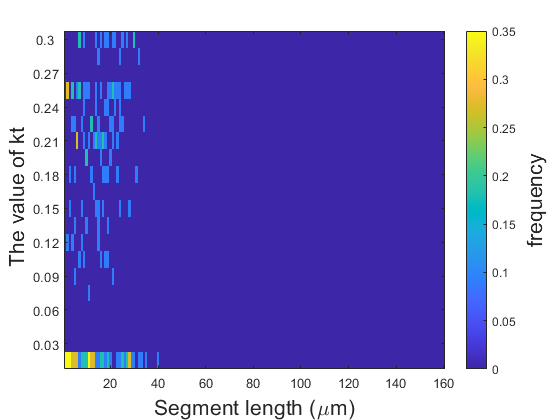

%%%%%%%%%%%%%%%%%%%%%    for terminal
% data up-limit

edges = 0:0.015:0.3;

for cx = 1: numberOfClasses
    
    ktOftmeSeries = [];
    
    for tx = 1: size(groupOfKT, 2)
    
        for ii = 1: showCut
   
        h  = histogram(groupOfKT{cx, tx}(:, ii), edges,'Normalization','probability');
        ktOftmeSeries = [ktOftmeSeries, h.Values']; 
   
        end
   
    clims = [0, 0.35];
    imagesc(ktOftmeSeries, clims);

    set(gca,'ydir','normal')  %%%  y-axis down-to-up
    set(gca, 'YTickLabel', yy)
    %set(gca, 'XTickLabel', xx, 'FontSize', 8)
    xlabel('Segment length (\mum)', 'FontSize', 16);
    ylabel(' The value of kt' ,'FontSize', 16);
    colorbar()
    ff = colorbar;
    ylabel(ff, 'frequency', 'FontSize', 16);
    set(ff, 'ylim', [0, clims(2)])

    saveFileNams = strcat(outputOfImagesc , 'Time series distribution of kt_', neuronType, '_', lab_name, '_',neuron_names{cx}, dendriteType{tx},  '.fig');
    saveas(gcf, saveFileNams, 'fig') ;
    saveFileNams = strcat(outputOfImagesc , 'Time series distribution of kt_', neuronType, '_', lab_name, '_',neuron_names{cx}, dendriteType{tx}, '.png');
    saveas(gcf, saveFileNams, 'png') ;

    end % end of tx
    
end % end of cx


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

## plot Boxplot for segment number

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
boxplotOutput = strcat(directory_out, 'boxplot/', lab_name, '/');
folderExist = exist(boxplotOutput, 'dir');
if folderExist == 0
     mkdir(boxplotOutput)
end

rng('default')  % For reproducibility 


 for tx = 1: numberOfType
     
    groupOfNumSegments = [];
    nameOfGroup = []; 
    groupString = 1: length(neuron_names);
    meanOfgroupSegment = [];
    SDOfgroupSegment = [];
     
     for cx = 1: numberOfClasses 
     
        nnn = numberOfSegmentsForNeuron{tx}(cx, 1: numberOfNeuronsInClass(cx, 1));
        groupOfNumSegments = [groupOfNumSegments; nnn'];

## mean & SD for group segment number

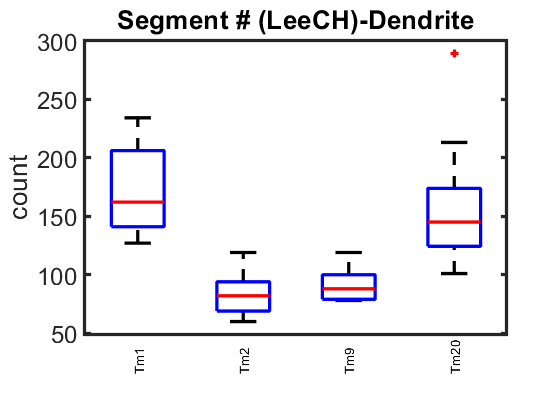

        meanOfgroupSegment(cx) = mean(nnn);
        SDOfgroupSegment(cx) = std(nnn);
    
        uuu = repmat (neuron_names{cx}, numberOfNeuronsInClass(cx, 1), 1);
        uuu = string(uuu); % change charact to string array 
        nameOfGroup = [nameOfGroup; uuu];
        
     end % end of cx

    h = boxplot(groupOfNumSegments, nameOfGroup, 'LabelOrientation', 'inline');
    
    set(h, 'LineWidth', 2.5)
    ylabel('count',  'FontSize', 18)
    title(strcat('Segment # (', lab_name, ')-', dendriteType{tx} ),  'FontSize', 18)
    set(gca,'FontSize',18, 'LineWidth', 2.5)
    
    save figure
    saveFileNams = strcat(boxplotOutput , 'boxplot_SegmentNumberRoot', '_', lab_name, '_',neuron_names{cx}, dendriteType{tx},'.fig');
    saveas(gcf, saveFileNams, 'fig') ;
    saveFileNams = strcat(boxplotOutput, 'boxplot_SegmentNumberRoot', '_', lab_name, '_',neuron_names{cx}, dendriteType{tx}, '.png');
    saveas(gcf, saveFileNams, 'png') ;
    
 end


 
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

## Get the average segment length

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%


for tx =1 : numberOfType

    averageLength = {};
    meanOfSegment = [];
    meanOfMeanLength =[];
    
    for  cx = 1: numberOfClasses
    
        for nx = 1: numberOfNeuronsInClass(cx)
        
            if modeOfStructureFlag == 5

## for basal 3, apical 4

                averageLength{cx, nx}  = mean( Tm{cx, nx}.length(Tm{cx, nx}.structureID == (tx + 2)));
                
            else
        
                averageLength{cx, nx}  = mean( Tm{cx, nx}.length);
            
            end
        end
    
        mmm = [averageLength{cx, 1: numberOfNeuronsInClass(cx)}];
        meanOfSegment = [meanOfSegment; mmm'];

## mean & SD for group of average length

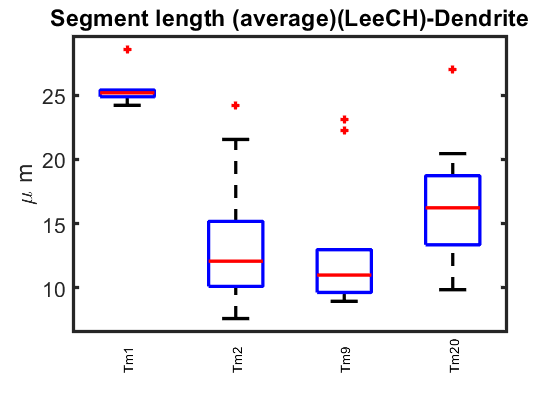

        meanOfMeanLength(cx) = mean(mmm);
        SDOfMeanLength(cx) = std(mmm); 
 
    end

    g = boxplot(meanOfSegment , nameOfGroup, 'LabelOrientation', 'inline');
    set(g, 'LineWidth', 2.5)
    ylabel('\mu m',  'FontSize', 18)
    title(strcat('Segment length (average)(', lab_name, ')-', dendriteType{tx}),  'FontSize', 18)
    set(gca,'FontSize',16, 'LineWidth', 2.5)

    saveFileNams = strcat(boxplotOutput, 'boxplot_averageSegmentLengthRoot', '_', lab_name, '_', neuron_names{cx}, dendriteType{tx}, '.fig');
    saveas(gcf, saveFileNams, 'fig') ;
    saveFileNams = strcat(boxplotOutput,'boxplot_averageSegmentLengthRoot', '_', lab_name, '_', neuron_names{cx}, dendriteType{tx}, '.png');
    saveas(gcf, saveFileNams, 'png') ;

end


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

## plot kb, kt ratio v.s segment length

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
figure;
deltaFigureOutputPath = strcat(directory_out, 'deltaKBKT/', lab_name, '/');
folderExist = exist(deltaFigureOutputPath, 'dir');
if folderExist == 0
     mkdir(deltaFigureOutputPath)
end

for cx = 1: numberOfClasses
    
    for tx =1: size(groupOfKB, 2)
    
        deltaKBKT = (groupOfKB{cx, tx}- groupOfKT{cx, tx});
   
        for ix = 1: size(deltaKBKT, 1)

## -2 < = plot only <= 2

            BT_element =  deltaKBKT (ix, :);
            BT_less = BT_element(BT_element <= 2 & BT_element >= -2);
                
            plot(BT_less,  'Color', [0.7804    0.9412    0.6392])
        
            hold on
            
        end
        
         for  clx = 1: showCut 
            
            column = deltaKBKT(: , clx);

## -2 <= column <= 2 and isNaN

## mean of deltaKBKT

            ColumnLess2AndNotNaN = column(column <= 2 & ~isnan(column));
            Columnbetween2 = ColumnLess2AndNotNaN(ColumnLess2AndNotNaN >= -2);
            sumColumn = sum(Columnbetween2 );
            meanDeltaKBKT(clx) = sumColumn / length(Columnbetween2 );

## std of deltaKBKT

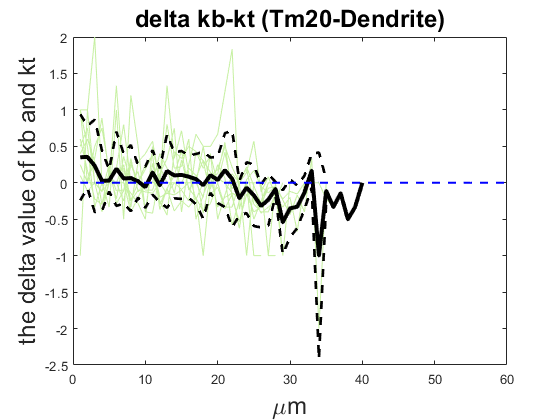

            square = (Columnbetween2 - meanDeltaKBKT(clx)) .* (Columnbetween2  - meanDeltaKBKT(clx));
            stdDeltaKBKT(clx) = (sum(square) / (length(Columnbetween2) -1))^(1/2);
            
         end
         
        upbound_delta = meanDeltaKBKT + stdDeltaKBKT;
        downbound_delta = meanDeltaKBKT - stdDeltaKBKT;
    
        plot(meanDeltaKBKT , 'k', 'LineWidth', 3)
        plot(upbound_delta , '--k', 'LineWidth', 2) 
        plot(downbound_delta , '--k',  'LineWidth', 2)
        plot(bins(1: showCut), 0 * bins(1: showCut), '--' ,'LineWidth', 1.5, 'Color', 'b')
        
        title(strcat('delta kb-kt (',neuron_names{cx},'-' ,dendriteType{tx},')'),  'FontSize', 18)
        xlabel ('\mum',  'FontSize', 18)
        ylabel ('the delta value of kb and kt',  'FontSize', 18)
        xlim([0, 60])
        hold off

        saveFileNams = strcat(deltaFigureOutputPath , 'deltakb-kt on region_', neuronType, '_', lab_name, '_',neuron_names{cx}, dendriteType{tx},'.fig');
        saveas(gcf, saveFileNams, 'fig') ;
        saveFileNams = strcat(deltaFigureOutputPath, 'deltakb-kt on region_', neuronType, '_', lab_name, '_',neuron_names{cx}, dendriteType{tx},'.png');
        saveas(gcf, saveFileNams, 'png') ;
        
    end
    
end


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

## Moving Averge filtering

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
matrixOutputPath = strcat(directory_out, 'matrixOutput/', lab_name, '/');
folderExist = exist(matrixOutputPath, 'dir');
if folderExist == 0
     mkdir(matrixOutputPath)
end

span = 3;

for cx = 1: numberOfClasses

        for tx = 1: size(groupOfKB, 2)
            
        rm0OfGroupOfKB = groupOfKB{cx, tx}(groupOfAtRisk{cx, tx}(:, 1) ~= 0, :);
        rm0OfGroupOfKT = groupOfKT{cx, tx}(groupOfAtRisk{cx, tx}(:, 1) ~= 0, :); 
        
            for  clx = 1: showCut
           
                column = rm0OfGroupOfKB(: , clx);

## column <= 1 and isNaN

## mean of KB less than 1

                ColumnLess1AndNotNaN = column(column <= 1 & ~isnan(column));
                sumColumnLess1 = sum(ColumnLess1AndNotNaN);
                meanOfKB(clx) = sumColumnLess1 / length(ColumnLess1AndNotNaN);
          
                column = rm0OfGroupOfKT(: , clx);

## column <= 1 and isNaN

## mean of KT less than 1

                ColumnLess1AndNotNaN = column(column <= 1 & ~isnan(column));
                sumColumnLess1 = sum(ColumnLess1AndNotNaN);
                meanOfKT(clx) = sumColumnLess1 / length(ColumnLess1AndNotNaN);
    
            end

## moving average fitering

       movMean_KB{cx, tx} = movmean(meanOfKB, span);
       saveFileNams = strcat(matrixOutputPath , 'KB_series_', neuronType, '_', lab_name, '_',neuron_names{cx},'_', dendriteType{tx},'.csv');
       csvwrite(saveFileNams, movMean_KB{cx, tx}')
       
       movMean_KT{cx, tx} = movmean(meanOfKT, span);
       saveFileNams = strcat(matrixOutputPath , 'KT_series_', neuronType, '_', lab_name, '_',neuron_names{cx},'_', dendriteType{tx},'.csv');
       csvwrite( saveFileNams, movMean_KT{cx, tx}')
       
       end
end

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

## autocorrelation function (Yu)

%%%%%%%%%%%%%%%%%%%%%%%%%%

## plot number of brancing and terminal number of neuron

e.g. 1st neuron

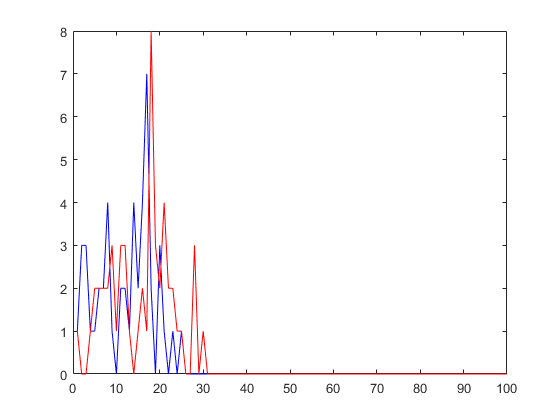

plot(numOfBr{1, 1}.data, 'b')
hold on
plot(numOfTe{1,1}.data, 'r')
xlim([0 , 1/2* length(numOfTe{1,1}.data)])
hold off

%{

## test for autocorrelaation function

data = [ 1, 2, 5, 0, 3];
N = length(data);
y_mean = mean(data);
sk = zeros(N + 1, 1);

for lag = 1: N
    y_lag = zeros(N, 1);
        
    for n = (lag + 1): N 
         y_lag(n) =  (data(n) - y_mean)* (data(n - lag) - y_mean);
    end
        
    sk(lag +1) = (1/ N)* sum(y_lag);
    sk0 =  (1/ N)* sum((data - y_mean) .^2);  
    sk(1) = sk0 ;
    
    if isempty(sk)
                    
       disp('arrary is empty')
       y = 0;
        continue
    else
      y = sk / sk(1);
                    
    end
end
disp(y)

%}
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

## Calculate autocorrelation function(ACF) of Br and Te

ACF_collect_Br = cell(length(numberOfClasses), size(groupOfBr, 2));
ACF_collect_Te =cell(length(numberOfClasses), size(groupOfBr, 2));


for cx = 1: numberOfClasses
    
    ACF_OutputPath = strcat(directory_out, 'ACF/', lab_name, '/', neuron_names{cx}, '/');
    %mkdir(ACF_OutputPath)
    
    for tx = 1: size(groupOfBr, 2)
     
        for nx = 1: size(groupOfBr{cx, tx}, 1)
    
            data_n = [groupOfBr{cx, tx}(nx, :); groupOfTe{cx, tx}(nx, :)];
            disp(nx);
            
            for ix = 1: size(data_n, 1)
        
                data = data_n(ix, :);
                
                % find the last one value
                dataLength= find(data, 1, 'last' );
                disp(dataLength);
                data = data(1: dataLength);

## define ACF

                 N = length(data);
                 if N ==0
                     break
                 end
                 
                 y_mean = mean(data);
                 sk = zeros(N + 1, 1);
    
                 for lag = 1: N
                     y_lag = zeros(N, 1);
        
                     for n = (lag + 1): N 
                          y_lag(n) =  (data(n) - y_mean)* (data(n - lag) - y_mean);
                     end
        
                    sk(lag +1) = (1/ N)* sum(y_lag);
                    sk0 =  (1/ N)* sum((data - y_mean) .^2);  
                    sk(1) = sk0 ;
        
                 end
                
                if isempty(sk)
                    
                    disp('arrary is empty')
                    continue
                else
                        y = sk / sk(1);
                end
                
            
                %{
                % by matlab default ACF
                %lengthOfLags = dataLength - 1;
                y = autocorr(data(1: dataLength - 1));
                %}

## collect ACF of Br and Te, respectively

                if ix == 1
                    ACF_collect_Br{cx, tx}{nx} = y;
                elseif ix == 2
                    ACF_collect_Te{cx, tx}{nx} = y;
                else
                    disp('Data type error')
                end

## plot result of ACF

     1



    33



    34



     2



    29



    30



     3



    35



    36



     4



    32



    33



     5



    33



    34



     6



    31



    33



     1



    28



    35



     2



    17



    23



     3



    21



    23



     4



    20



    23



     5



    23



    24



     6



    31



    33



     7



    23



    25



     8



    25



    26



     9



    17



    19



    10



    20



    22



    11



    15



    16



    12



    20



    22



    13



    18



    20



    14



    21



    23



     1



    22



    25



     2



    18



    20



     3



    19



    22



     4



    24



    29



     5



    29



    33



     6



    31



    33



     7



    18



    22



     8



    22



    24



     9



    18



    22



    10



    21



    23



     1



    25



    30



     2



    25



    27



     3



    17



    19



     4



    25



    29



     5



    25



    30



     6



    28



    31



     7



    31



    40



     8



    34



    35



     9



    27



    30



    10



    38



    40



    11



    23



    27



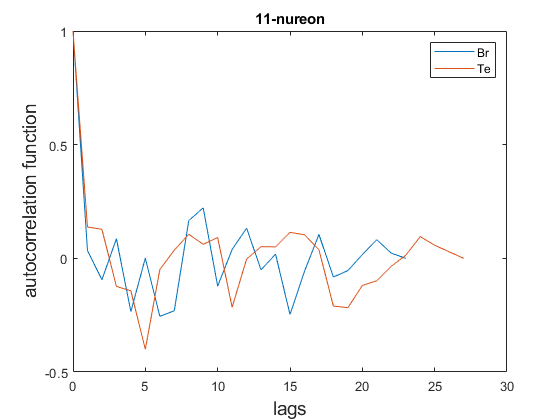

                x_lags = 0: length(y) - 1;
                plot(x_lags, y)
                %xlim([0 , 50])
                hold on
        
            end
            title(strcat(num2str(nx), '-nureon'))
            legend(['Br'; 'Te'])
            xlabel('lags', 'fontsize', 14)
            ylabel('autocorrelation function', 'fontsize', 14)
            hold off
            
            ACF_OutputPath_n = strcat(ACF_OutputPath, dendriteType{tx}, num2str(nx),'/');
            folderExist = exist(ACF_OutputPath_n, 'dir');
            if folderExist == 0
                mkdir(ACF_OutputPath_n)
            end
            
            
            saveFileNams = strcat(ACF_OutputPath_n , 'ACFofkb-kt_', neuronType, '_', lab_name, '_',neuron_names{cx}, dendriteType{tx}, num2str(nx),'.fig');
            saveas(gcf, saveFileNams, 'fig') ;
            saveFileNams = strcat(ACF_OutputPath_n, 'ACFofkb-kt_', neuronType, '_', lab_name, '_',neuron_names{cx}, dendriteType{tx}, num2str(nx),'.png');
            saveas(gcf, saveFileNams, 'png') ;
        
        end
    end
end


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

## plot mean and variance of ACF for Br and Te in the same grop %%

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
label = ['Br'; 'Te']; 
ACF_collect = {ACF_collect_Br; ACF_collect_Te};
dataSum = cell(numberOfClasses, size(ACF_collect_Br, 2));
dataLengthForMean = cell(numberOfClasses, size(ACF_collect_Br, 2));
ACF_OutputPath = strcat(directory_out, 'ACF/', lab_name, '/');

for cx = 1: numberOfClasses

    for tx = 1: size(ACF_collect_Br, 2) 
        
        for ix = 1:2 % br and Te
            
            ACF_collect_type = ACF_collect{ix};
            acfLength = size(ACF_collect_type{cx, tx}, 2);
            SeriersLength = zeros(acfLength, 1);
            
            %%% Find the max series length
            for nx = 1: acfLength
                
                Series = ACF_collect_type{cx, tx}{nx};
                
                SeriersLength(nx) = size(Series, 1);
                
            end
            
            maxSeriesLength = max(SeriersLength);
            
            sumOfSeries = zeros(1, maxSeriesLength);
            
            %%% summation of Series
            for nx = 1: acfLength
                
                Series = ACF_collect_type{cx, tx}{nx};
                
                for sx = 1: SeriersLength(nx)
                    
                    sumOfSeries(1, sx) = sumOfSeries(1, sx) + Series(sx, 1);
                
                end
                
            end

            dataSum{cx, tx}{ix} = sumOfSeries;
            dataLengthForMean{cx, tx}{ix} = sumOfSeries ./ sumOfSeries(1);
            x_lags = 0: length(sumOfSeries) - 1; 
            
            plot(x_lags, dataLengthForMean{cx, tx}{ix});
            %legend(label(ix))
            xlabel('lags', 'fontsize', 14)
            ylabel('autocorrelation function', 'fontsize', 14)
            
            ACF_OutputPath_mean = strcat(ACF_OutputPath, 'mean_stdOfACF/');
            folderExist = exist(ACF_OutputPath_mean, 'dir');
            if folderExist == 0
                mkdir(ACF_OutputPath_mean)
            end
            
            saveFileNams = strcat(ACF_OutputPath_mean , 'ACFofkb_mean_std_', label(ix) , '_', neuronType, '_', lab_name, '_',neuron_names{cx}, dendriteType{tx},'.fig');
            saveas(gcf, saveFileNams, 'fig');
            saveFileNams = strcat(ACF_OutputPath_mean, 'ACFofkb_mean_std_', label(ix) , '_', neuronType, '_', lab_name, '_',neuron_names{cx}, dendriteType{tx},'.png');
            saveas(gcf, saveFileNams, 'png');

## plot specific region %%%

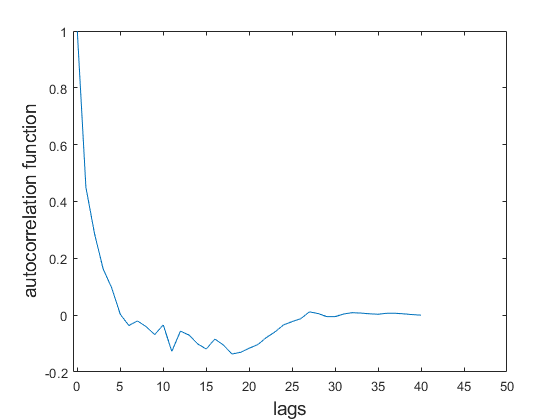

            plot(x_lags, dataLengthForMean{cx, tx}{ix});
            xlabel('lags', 'fontsize', 14)
            ylabel('autocorrelation function', 'fontsize', 14)
            xlim([-0.5,  50])
            saveFileNams = strcat(ACF_OutputPath_mean , 'ACFofkb_mean_std_s_', label(ix) , '_', neuronType, '_', lab_name, '_',neuron_names{cx}, dendriteType{tx},'.fig');
            saveas(gcf, saveFileNams, 'fig');
            saveFileNams = strcat(ACF_OutputPath_mean , 'ACFofkb_mean_std_s_', label(ix) , '_', neuronType, '_', lab_name, '_',neuron_names{cx}, dendriteType{tx},'.png');
            saveas(gcf, saveFileNams, 'png');
            
 
        end       
    end   
end

for cx = 1: numberOfClasses

    for tx = 1: size(ACF_collect_Br, 2) 
        
        for ix = 1:2 % br and Te
            x_lags = 0: length(dataLengthForMean{cx, tx}{ix}) - 1;

## plot specific region %%%

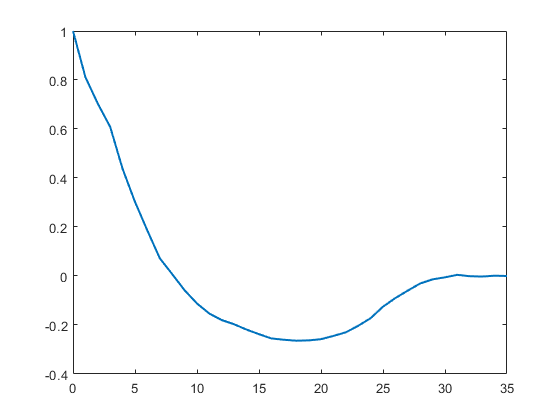

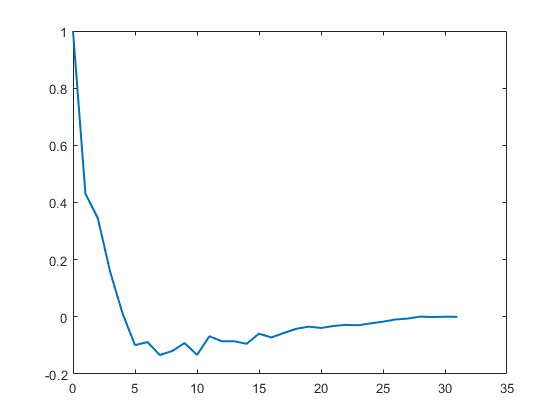

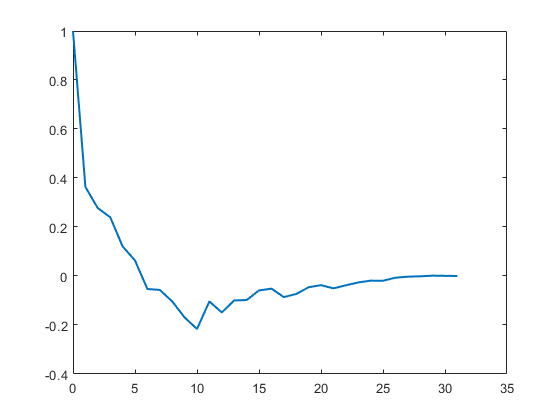

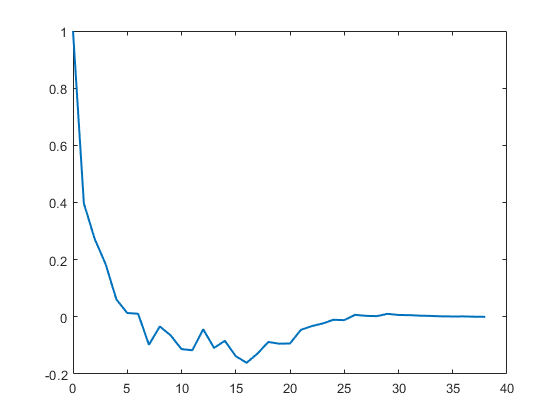

            plot(x_lags, dataLengthForMean{cx, tx}{ix}, 'LineWidth', 1.5);

            hold on

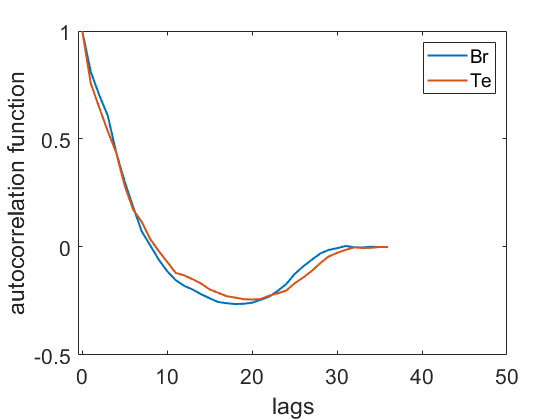

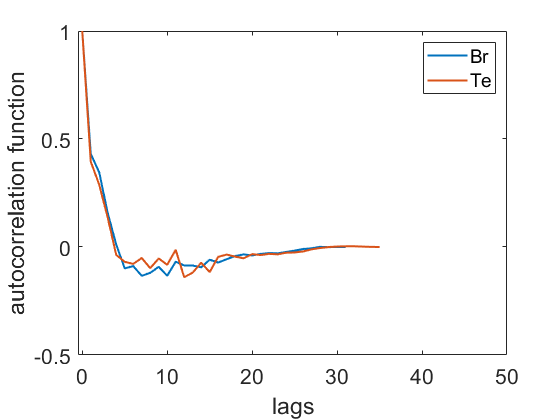

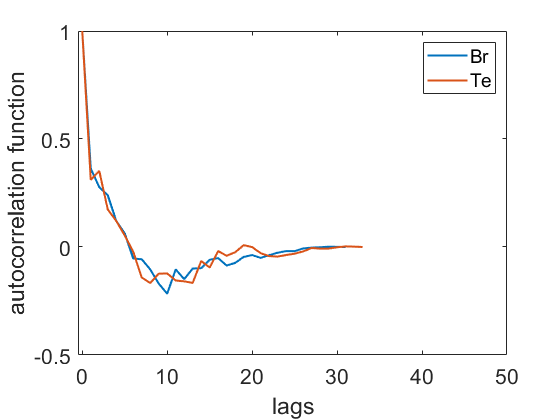

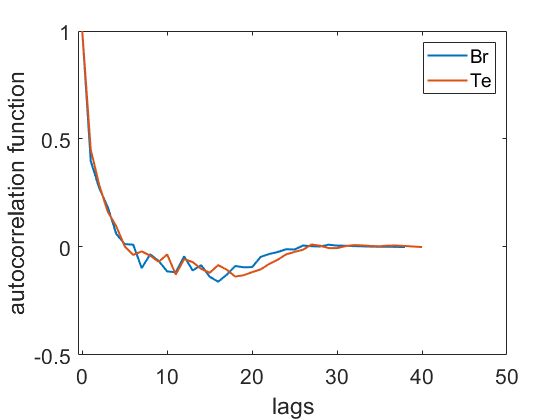

            
        end
        xlabel('lags', 'fontsize', 18)
        ylabel('autocorrelation function', 'fontsize', 18)
        xlim([-0.5,  50])
        ylim([ -0.5, 1.0])
        legend (['Br'; 'Te'], 'fontsize', 14)
        set(gca,'FontSize',16)
        hold off
        
        ACF_OutputPath_mean = strcat(ACF_OutputPath, 'mean_stdOfACF_merger/');
        folderExist = exist(ACF_OutputPath_mean, 'dir');
        if folderExist == 0
            mkdir(ACF_OutputPath_mean)
        end
        
        saveFileNams = strcat(ACF_OutputPath_mean , 'ACFof_mean_kbkt_', neuronType, '_', lab_name, '_',neuron_names{cx}, dendriteType{tx},'.fig');
        saveas(gcf, saveFileNams, 'fig');
        saveFileNams = strcat(ACF_OutputPath_mean , 'ACFof_mean_kbkt_', neuronType, '_', lab_name, '_',neuron_names{cx}, dendriteType{tx},'.png');
        saveas(gcf, saveFileNams, 'png');
        
    end
    
end

## plot kb for agroup

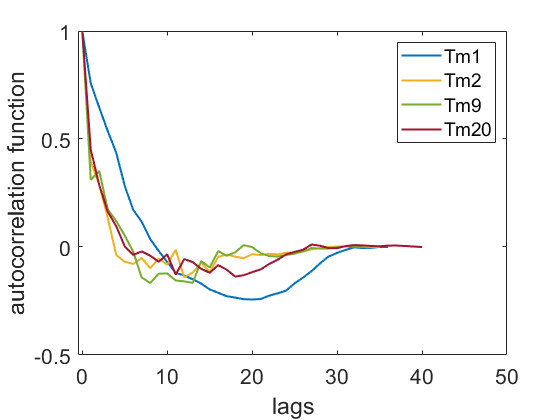

prop ={'kb'; 'kt'};
line_color = {[0 0.4470 0.7410]; [0.9290 0.6940 0.1250]; [0.4660 0.6740 0.1880] ; [0.6350 0.0780 0.1840]};
for ix = 1:2
    
    for cx = 1: numberOfClasses

        for tx = 1: size(ACF_collect_Br, 2) 
            x_lags = 0: length(dataLengthForMean{cx, tx}{ix}) - 1;
            plot(x_lags, dataLengthForMean{cx, tx}{ix}, 'LineWidth', 1.5, 'Color', line_color{cx});    
            hold on
        end

    end
    xlabel('lags', 'fontsize', 18)
    ylabel('autocorrelation function', 'fontsize', 18)
    xlim([-0.5,  50])
    ylim([ -0.5, 1.0])
    legend (neuron_names, 'fontsize', 14)
    set(gca,'FontSize',16)
     hold off
     
     ACF_OutputPath_mean = strcat(ACF_OutputPath, 'mean_stdOfACF_merger/');
     folderExist = exist(ACF_OutputPath_mean, 'dir');
     if folderExist == 0
        mkdir(ACF_OutputPath_mean)
     end

    saveFileNams = strcat(ACF_OutputPath_mean , 'ACFof_mean_',  prop{ix}, '_', neuronType, '_', lab_name, '_', dendriteType{tx},'.fig');
    saveas(gcf, saveFileNams, 'fig');
    saveFileNams = strcat(ACF_OutputPath_mean , 'ACFof_mean_',  prop{ix}, '_', neuronType, '_', lab_name, '_', dendriteType{tx},'.png');
    saveas(gcf, saveFileNams, 'png');

end


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

## plot mean of Be and Te

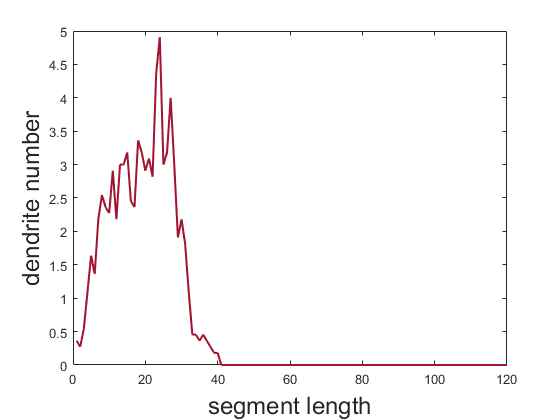

prop ={'Br'; 'Te'};
line_color = {[0 0.4470 0.7410]; [0.6350 0.0780 0.1840]};

NumberChangeOutputPath_mean = strcat(directory_out, 'mean_numberChange_BrTe/');

folderExist = exist(NumberChangeOutputPath_mean, 'dir');
if folderExist == 0
    mkdir(NumberChangeOutputPath_mean)
end

for cx = 1: numberOfClasses
    
    for tx = 1: size(groupOfBr, 2)
        %LengthOfGroup = size(sum(groupOfBr{cx}), 2 );
        maxLength = 3 * sum(sum(groupOfBr{cx}) ~= 0);
        meanOfBr = nanmean(groupOfBr{cx});
        plot(meanOfBr(1: maxLength),  'LineWidth', 1.5, 'Color', line_color{1})
        xlabel('segment length', 'fontsize', 18)
        ylabel('dendrite number', 'fontsize', 18)        
        
        saveFileNams = strcat(NumberChangeOutputPath_mean, 'BrNumChange_', neuronType, '_', lab_name, '_', neuron_names{cx}, '_',dendriteType{tx},'.fig');
        saveas(gcf, saveFileNams, 'fig');
        saveFileNams = strcat(NumberChangeOutputPath_mean, 'BrNumChange_', neuronType, '_', lab_name, '_', neuron_names{cx}, '_',dendriteType{tx},'.png');
        saveas(gcf, saveFileNams, 'png');
        

        maxLength = 3 * sum(sum(groupOfTe{cx}) ~= 0);
        meanOfTe = nanmean(groupOfTe{cx});
        plot(meanOfTe(1: maxLength ), 'LineWidth', 1.5, 'Color', line_color{2})
        xlabel('segment length', 'fontsize', 18)
        ylabel('dendrite number', 'fontsize', 18)
        
        saveFileNams = strcat(NumberChangeOutputPath_mean, 'TeNumChange_', neuronType, '_', lab_name, '_', neuron_names{cx}, '_',dendriteType{tx},'.fig');
        saveas(gcf, saveFileNams, 'fig');
        saveFileNams = strcat(NumberChangeOutputPath_mean, 'TeNumChange_', neuronType, '_', lab_name, '_', neuron_names{cx}, '_',dendriteType{tx},'.png');
        saveas(gcf, saveFileNams, 'png');
        
    end
     
end

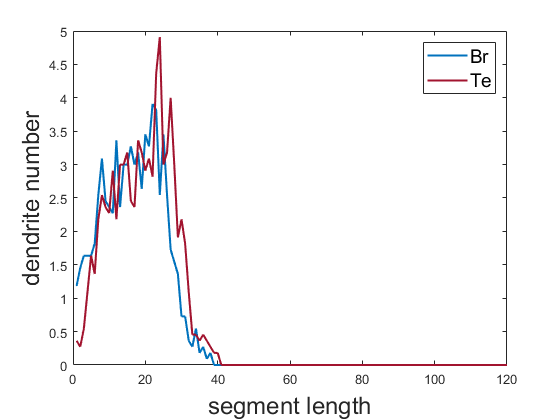

%Merge Br and Te
    
NumberChangeOut_mean_merger = strcat(directory_out, 'mean_numberChange_BrTe/MergeBrTe/');

folderExist = exist(NumberChangeOut_mean_merger, 'dir');
if folderExist == 0
    mkdir(NumberChangeOut_mean_merger)
end

for cx = 1: numberOfClasses
  
    for tx = 1: size(groupOfBr, 2)
        %LengthOfGroup = size(sum(groupOfBr{cx}), 2 );
        maxLength = 3 * sum(sum(groupOfBr{cx}) ~= 0);
        meanOfBr = nanmean(groupOfBr{cx});
        plot(meanOfBr(1: maxLength),  'LineWidth', 1.5, 'Color', line_color{1})
        hold on 
        
        maxLength = 3 * sum(sum(groupOfTe{cx}) ~= 0);
        meanOfTe = nanmean(groupOfTe{cx});
        plot(meanOfTe(1: maxLength ), 'LineWidth', 1.5, 'Color', line_color{2})
        xlabel('segment length', 'fontsize', 18)
        ylabel('dendrite number', 'fontsize', 18)
        legend (prop, 'fontsize', 14)
        hold off
        
        saveFileNams = strcat(NumberChangeOut_mean_merger, 'NumChangeMerger_', neuronType, '_', lab_name, '_', neuron_names{cx}, '_',dendriteType{tx},'.fig');
        saveas(gcf, saveFileNams, 'fig');
        saveFileNams = strcat(NumberChangeOut_mean_merger, 'NumChangeMerger_', neuronType, '_', lab_name, '_', neuron_names{cx}, '_',dendriteType{tx},'.png');
        saveas(gcf, saveFileNams, 'png');
        
    end
     
end


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

## Plot kb v.s N Or kt v.s N

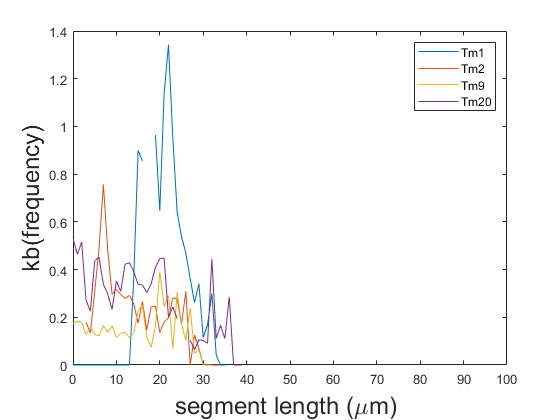

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
figure
%%% kb vs r
for cx = 1: numberOfClasses
    N =  mean(groupOfAtRisk{cx});
    KBmean = nanmean(groupOfKB{cx});
    lenOfKB = size(groupOfKB{cx}, 2);
    r = 0: lenOfKB -1 ;
    plot(r,KBmean)
    hold on     
end
xlabel('segment length (\mum) ', 'fontsize', 18)
ylabel('kb(frequency)', 'fontsize', 18)
xlim([0, 100])
legend(neuron_names)

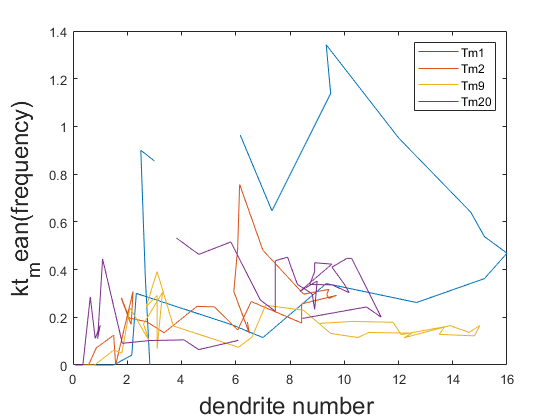


figure
%%% kb vs N
for cx = 1: numberOfClasses
    N =  mean(groupOfAtRisk{cx});
    KTmean = nanmean(groupOfKB{cx});
    lenOfKT = size(groupOfKT{cx}, 2);
    plot(N(1:  lenOfKT),KTmean)
    hold on     
end
xlabel('dendrite number ', 'fontsize', 18)
ylabel('kt_mean(frequency)', 'fontsize', 18)
legend(neuron_names)

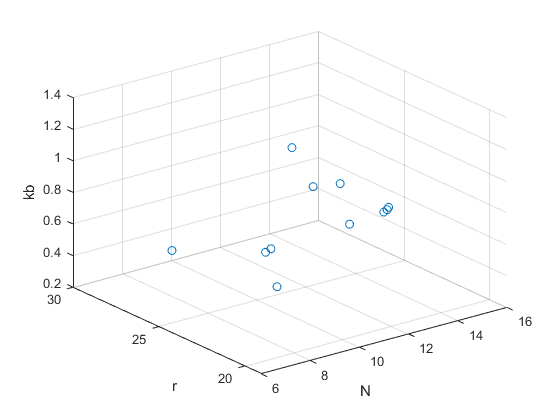


figure
%%% kb vs N vs r
N =  mean(groupOfAtRisk{1});
KBmean = mean(groupOfKB{1});
lenOfKB = size(groupOfKB{1}, 2);
r = 0: lenOfKB -1 ;
scatter3(N(1:  lenOfKB),r, KBmean)
xlabel('N')
ylabel('r')
zlabel('kb')

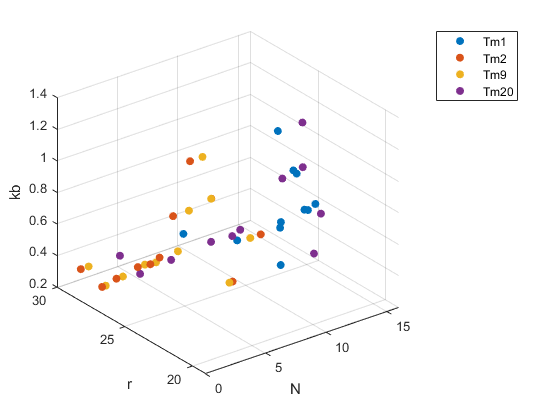



figure
%%% kb vs N vs r for all group
for cx = 1: numberOfClasses
    N =  mean(groupOfAtRisk{cx});
    KTmean = mean(groupOfKT{cx});
    lenOfKT = size(groupOfKT{cx}, 2);
    r = 0: lenOfKB -1 ;
    scatter3(N(1:  lenOfKT),r , KBmean, 'filled')
    hold on     
end
xlabel('N')
ylabel('r')
zlabel('kb')
legend(neuron_names)
hold off

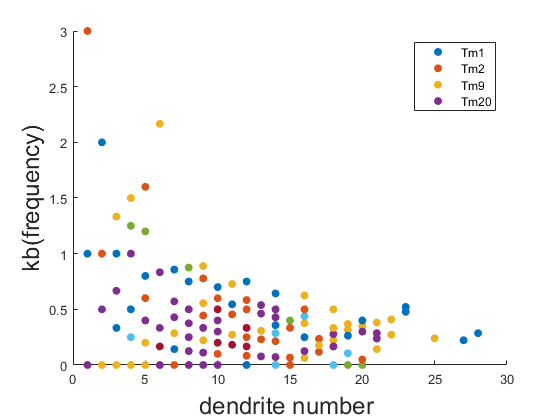

figure
innn = size(groupOfAtRisk{4}, 1);
for nx = 1 :  innn
    
    N = groupOfAtRisk{4};
    lll = size(groupOfKB{4}, 2);
    scatter(N(nx, 1 : lll), groupOfKB{4}(nx, :),'filled')
    hold on 
    
end
xlabel('dendrite number ', 'fontsize', 18)
ylabel('kb(frequency)', 'fontsize', 18)
legend(neuron_names)
hold off

## Plot Br and Te boxplot

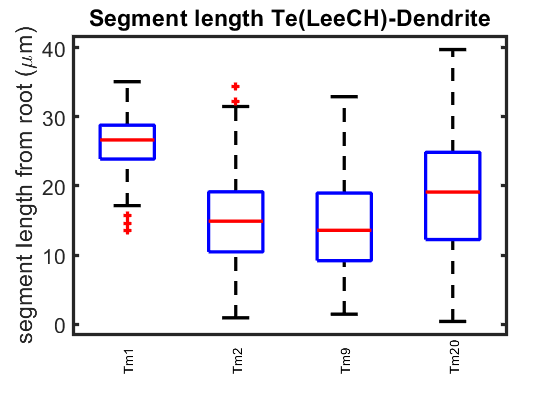

BrTeBoxplotPath = strcat(directory_out, 'boxplot/', lab_name,'/BrTe_boxplot/' );

folderExist = exist(BrTeBoxplotPath, 'dir');
if folderExist == 0
    mkdir(BrTeBoxplotPath)
end

for tx =1 : numberOfType

    averageLength = {};
    Segments_Br = [];
    Segments_Te = [];
    nameOfGroup_Br = [];
    nameOfGroup_Te = [];
    
    numBrInClass = cell(numberOfClasses, 1);
    numTeInClass = cell(numberOfClasses, 1);
    
    for  cx = 1: numberOfClasses
        numBr = [];
        numTe = [];
        
        for nx = 1: numberOfNeuronsInClass(cx)
        
            if modeOfStructureFlag == 5
                averageLength{cx, nx}  = mean( Tm{cx, nx}.length(Tm{cx, nx}.structureID == (tx + 2)));
                
            else
        
                %averageLength{cx, nx}  = mean( Tm{cx, nx}.length);
                BrInNeuron = gene{cx, nx}(gene{cx, nx}(:, 2) == 2, 1);
                numBr = [numBr; BrInNeuron];
                
                TeInNeuron = gene{cx, nx}(gene{cx, nx}(:, 2) == 0, 1);
                numTe = [numTe; TeInNeuron];
                
            end
            
        end
        numBrInClass{cx} = numBr;
        numTeInClass{cx} = numTe;
        % groupName for Br
        uuu = repmat (neuron_names{cx}, size(numBr, 1), 1);
        uuu = string(uuu); % change charact to string array
        % groupName for Te
        
        vvv = repmat (neuron_names{cx}, size(numTe, 1), 1);
        vvv = string(vvv); % change charact to string array
        
        nameOfGroup_Br = [nameOfGroup_Br; uuu];
        nameOfGroup_Te = [nameOfGroup_Te; vvv];
        
        Segments_Br = [Segments_Br; numBr];
        Segments_Te = [Segments_Te; numTe];
        
   
    end

    % For branching
    g = boxplot(Segments_Br , nameOfGroup_Br, 'LabelOrientation', 'inline');
    set(g, 'LineWidth', 2.5)
    ylabel('segment length from root (\mum)', 'FontSize', 18)
    title(strcat('Segment length Br(', lab_name, ')-', dendriteType{tx}), 'FontSize', 16)
    set(gca,'FontSize',16, 'LineWidth', 2.5)
    
    saveFileNams = strcat(BrTeBoxplotPath, 'boxplot_SegmentLengthRoot_Br_', lab_name, '_', neuron_names{cx}, dendriteType{tx}, '.fig');
    saveas(gcf, saveFileNams, 'fig') ;
    saveFileNams = strcat(BrTeBoxplotPath,'boxplot_SegmentLengthRoot_Br_', lab_name, '_', neuron_names{cx}, dendriteType{tx}, '.png');
    saveas(gcf, saveFileNams, 'png') ;
    
    % For terminating
    g = boxplot(Segments_Te , nameOfGroup_Te, 'LabelOrientation', 'inline');
    set(g, 'LineWidth', 2.5)
    ylabel('segment length from root (\mum)', 'FontSize', 18)
    title(strcat('Segment length Te(', lab_name, ')-', dendriteType{tx}), 'FontSize', 16)
    set(gca,'FontSize',16, 'LineWidth', 2.5)

    saveFileNams = strcat(BrTeBoxplotPath, 'boxplot_SegmentLengthRoot_Te_', lab_name, '_', neuron_names{cx}, dendriteType{tx}, '.fig');
    saveas(gcf, saveFileNams, 'fig') ;
    saveFileNams = strcat(BrTeBoxplotPath,'boxplot_SegmentLengthRoot_Te_', lab_name, '_', neuron_names{cx}, dendriteType{tx}, '.png');
    saveas(gcf, saveFileNams, 'png') ;

end

%%% plot mean l from root v.s distance E from root
L = [];
E = [];
figure
for cx = 1: numberOfClasses
for nx = 1: numberOfNeuronsInClass(cx)
    BBB = B_tree(trees{cx,nx});
    E_B1 = eucl_tree(trees{cx,nx});
    L_B2 = Pvec_tree(trees{cx,nx});
    f3 = scatter(mean(L_B2(BBB)), mean(E_B1(BBB)));
    L = [L; mean(L_B2(BBB))];
    E = [E; mean(E_B1(BBB))];
    hold on
end
end

x = 0: 0.5: 30;
f1 = plot(x, x, '--', "LineWidth", 2.5);

b1 = L\E

b1 = 0.6053

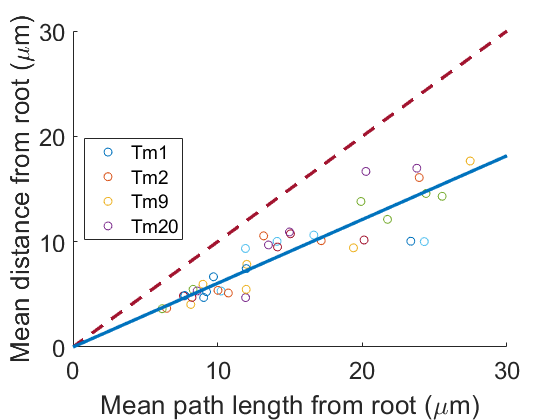

f2 = plot(x, b1* x,"LineWidth", 2.5);

legend_name = neuron_names;
%{
legend_name{end + 1} = 'equal line';
legend_name{end + 1} = 'linear regression' 
%}
legend(legend_name, "FontSize", 14, "Location", "west")
xlabel('Mean path length from root (\mum)')
ylabel('Mean distance from root (\mum)')
set(gca, "FontSize", 18)
hold off



figure
L = [];
E = [];
figure
for cx = 1: numberOfClasses
for nx = 1: numberOfNeuronsInClass(cx)
    TTT = T_tree(trees{cx,nx});
    E_T1 = eucl_tree(trees{cx,nx});
    L_T1 = Pvec_tree(trees{cx,nx});
    f3 = scatter(mean(L_T1(TTT)), mean(E_T1(TTT)));
    L = [L; mean(L_T1(TTT))];
    E = [E; mean(E_T1(TTT))];
    hold on
end
end

x = 0: 0.5: 30;
f1 = plot(x, x, '--', "LineWidth", 2.5);

b1 = L\E

b1 = 0.5603

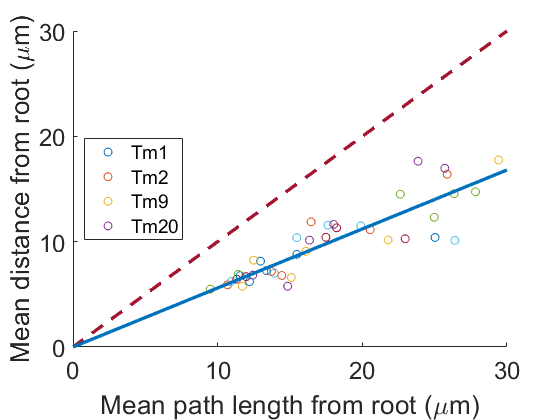

f2 = plot(x, b1* x,"LineWidth", 2.5);

legend_name = neuron_names;
%{
legend_name{end + 1} = 'equal line';
legend_name{end + 1} = 'linear regression' 
%}
legend(legend_name, "FontSize", 14, "Location", "west")
xlabel('Mean path length from root (\mum)')
ylabel('Mean distance from root (\mum)')
set(gca, "FontSize", 18)
hold off




%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%
%%%%%%%%%%%%    Coding ends here
%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%